[0.5 1 0 5 3]

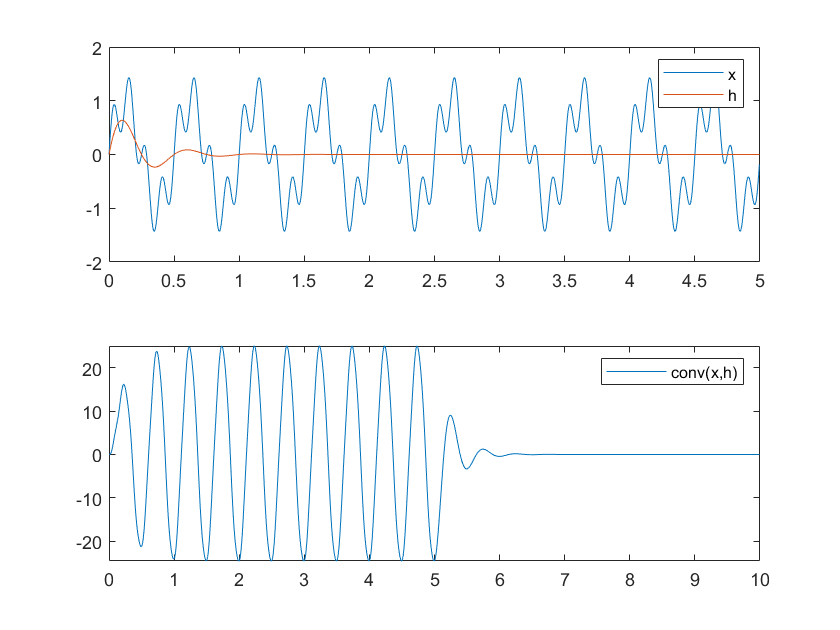

dt=5/1000;
t=0:dt:5-dt;
x=sin(4*pi*t)+0.5.*sin(16*pi.*t);
h=sin(2*pi*2*t).*exp(-4.*t);
y=conv(x,h);
t2=dt*(0:length(y)-1);
figure
subplot(2,1,1);
plot(t,x,t,h);
legend('x','h');
subplot(2,1,2);
plot(t2,y);
legend('conv(x,h)');

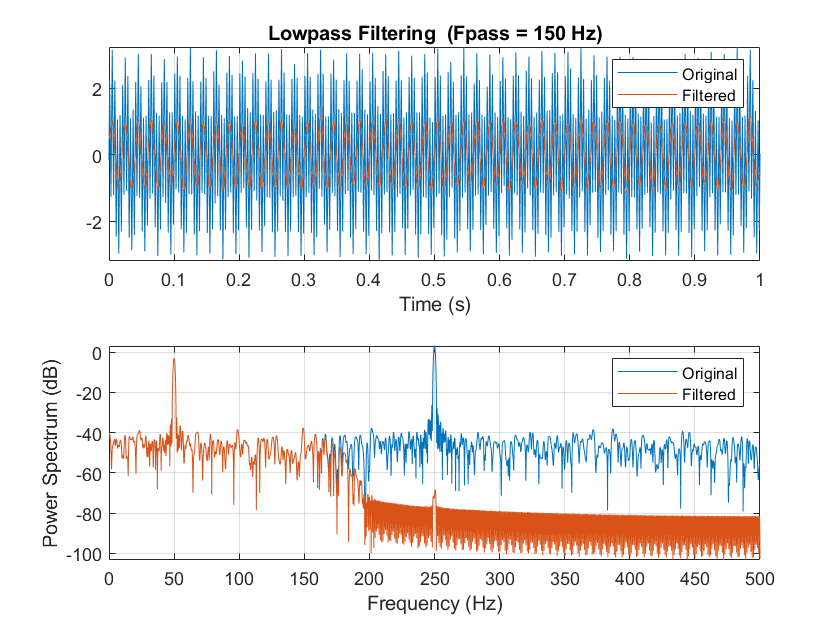

fs = 1e3;
t = 0:1/fs:1;
%signal to be filtered
x = [1 2]*sin(2*pi*[50 250]'.*t) + randn(size(t))/10;
lowpass(x,150,fs);

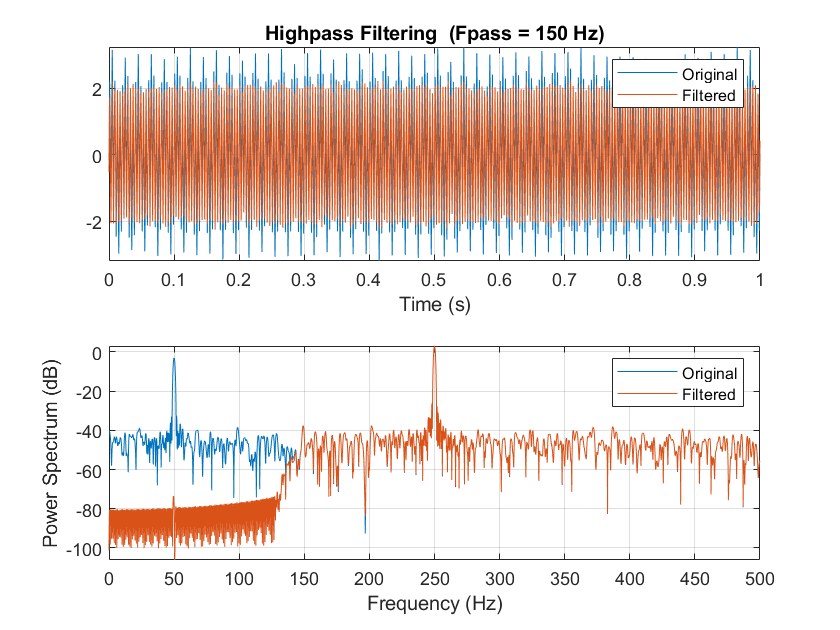

 %filtered signal
%[Y,D] = lowpass(...) returns the digital filter, D, used to
%filter the signal. Call fvtool(D) to visualize the filter
%response.
figure
highpass(x,150,fs);

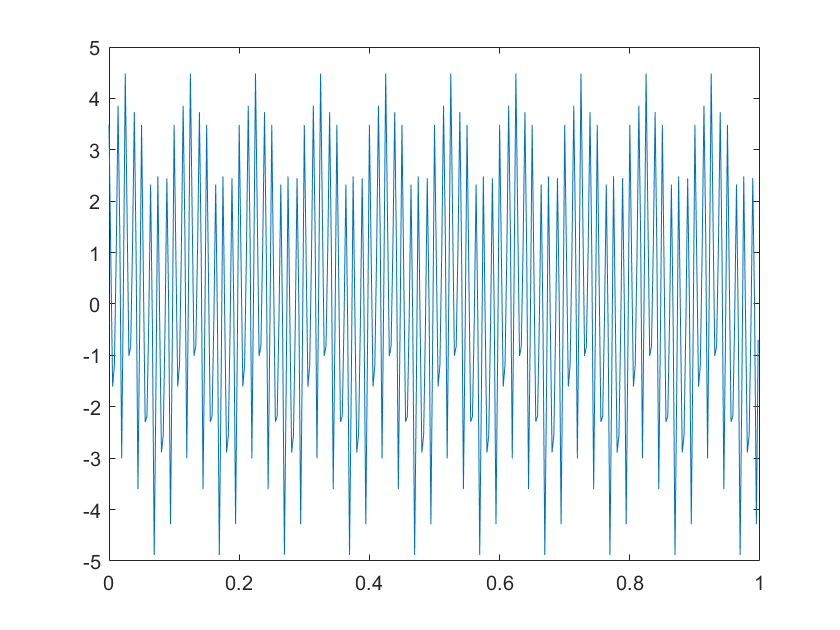

fs=360;
dt=1/fs;
t=0:dt:1-dt;
x=sin(2*pi*10.*t)+3*sin(2*pi*80.*t+(20))+sin(2*pi*120.*t+(40));
figure
plot(t,x)
xlim([0 1]);

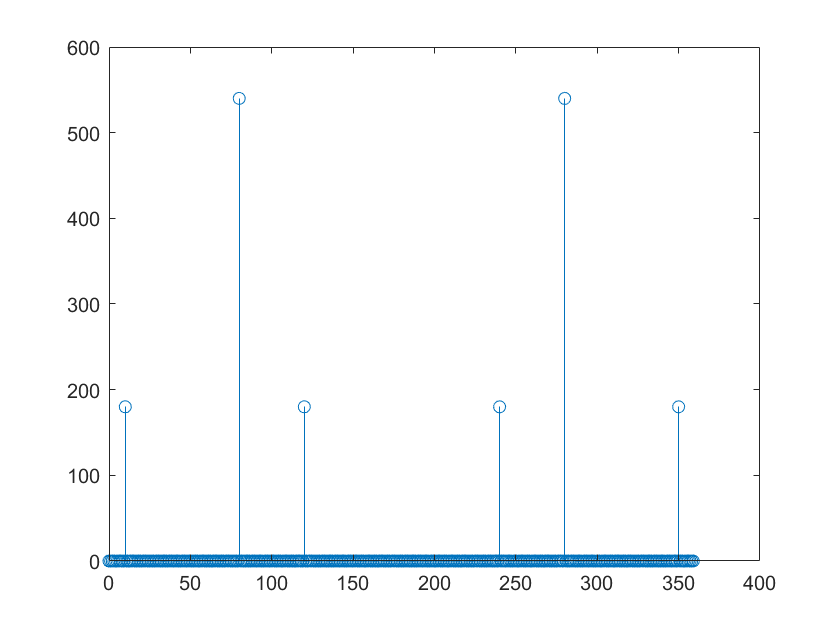

X=fft(x);
mag=abs(X);
n=length(t);
df=fs/n;
f=df*(0:n-1);
figure
stem(f,mag)

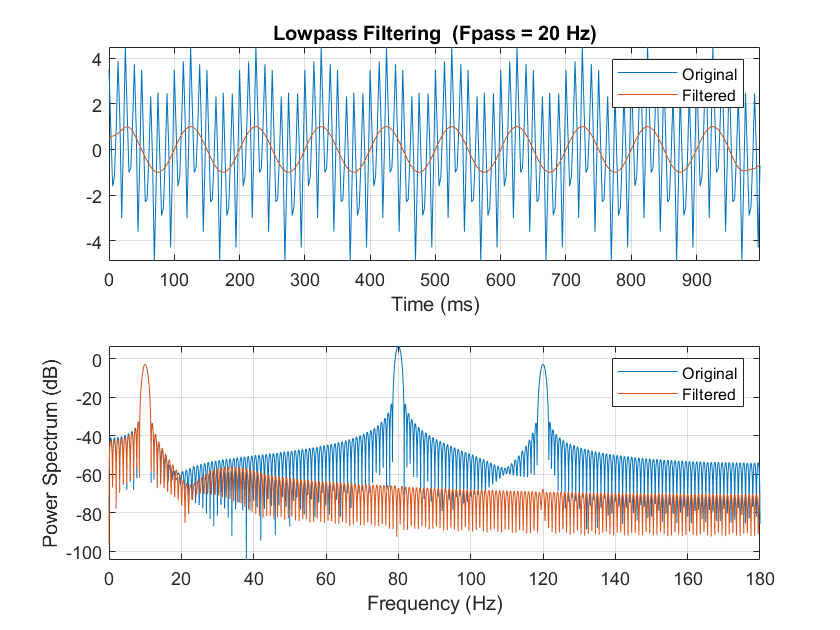

figure
[x1 d]=lowpass(x(1:360),20,fs);
figure
lowpass(x(1:360),20,fs);

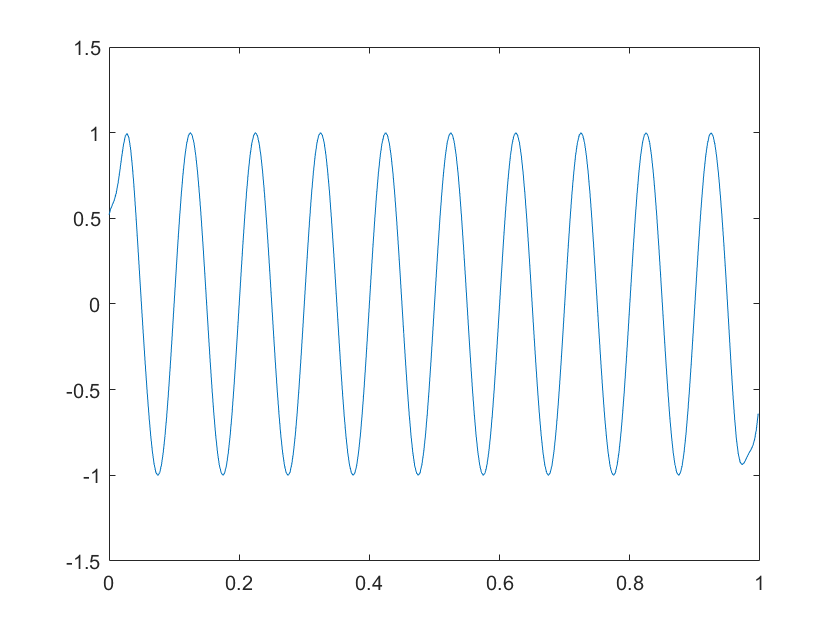

figure
plot(t,x1)

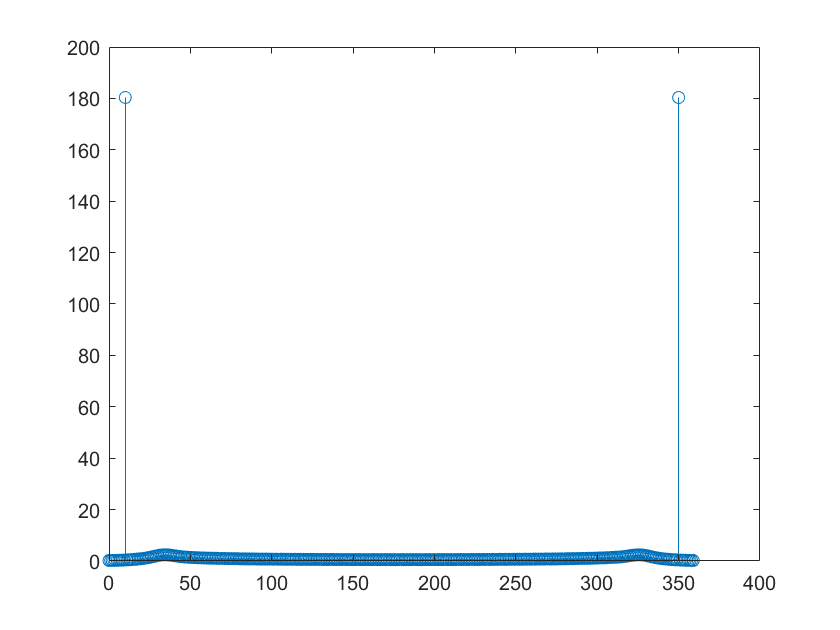

X=fft(x1);
mag=abs(X);
n=length(t);
df=fs/n;
f=df*(0:n-1);
figure
stem(f,mag)

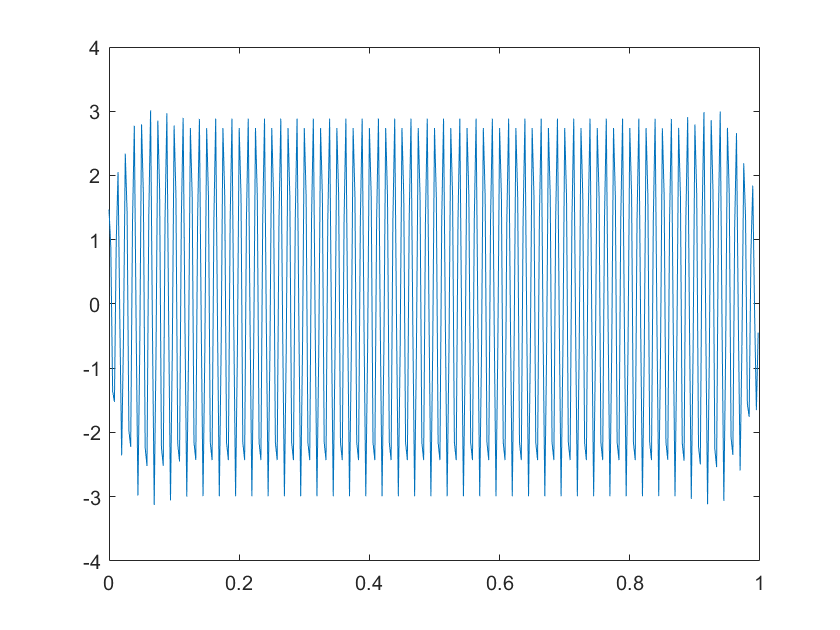

figure


x2=bandpass(x,[79 81],fs);
plot(t,x2)

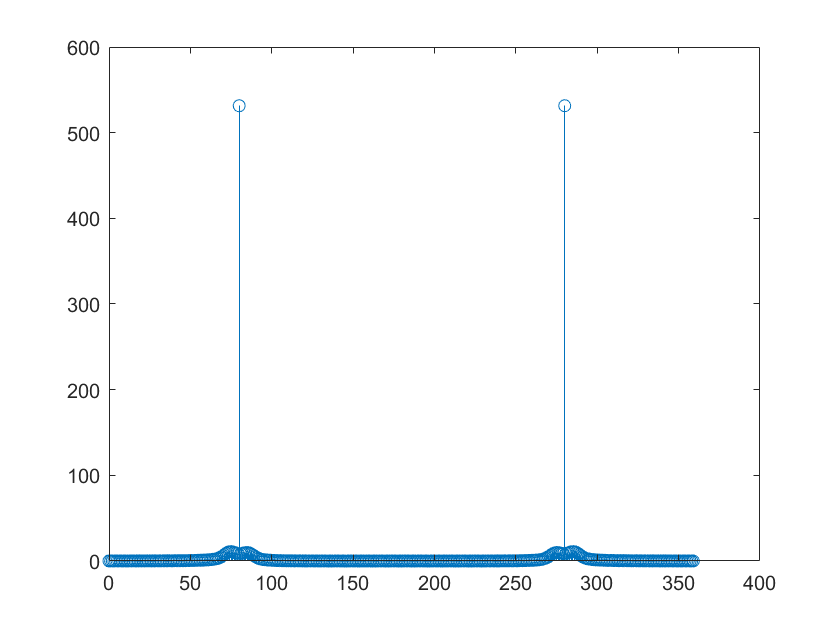

X=fft(x2);
mag=abs(X);
n=length(t);
df=fs/n;
f=df*(0:n-1);
figure
stem(f,mag)

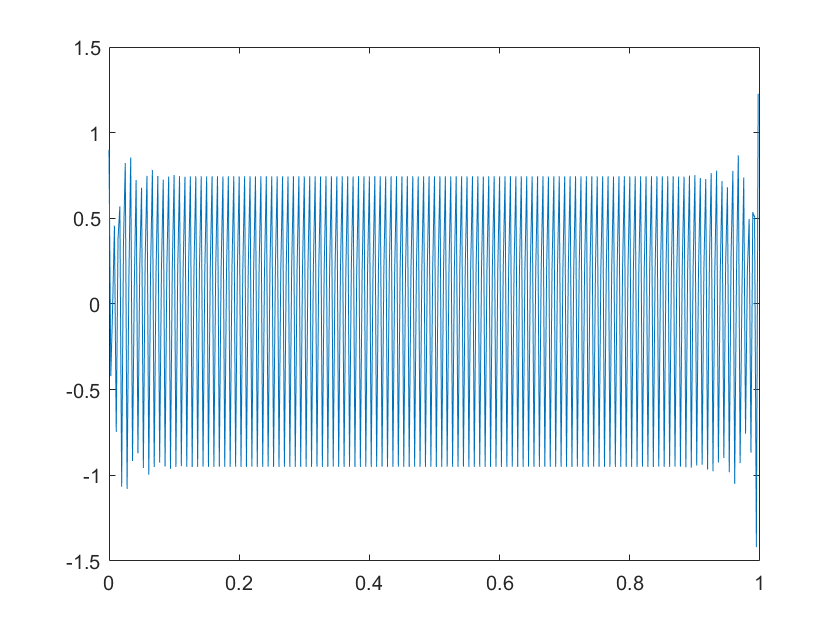

figure
x3=highpass(x(1:360),100,fs);
plot(t,x3)

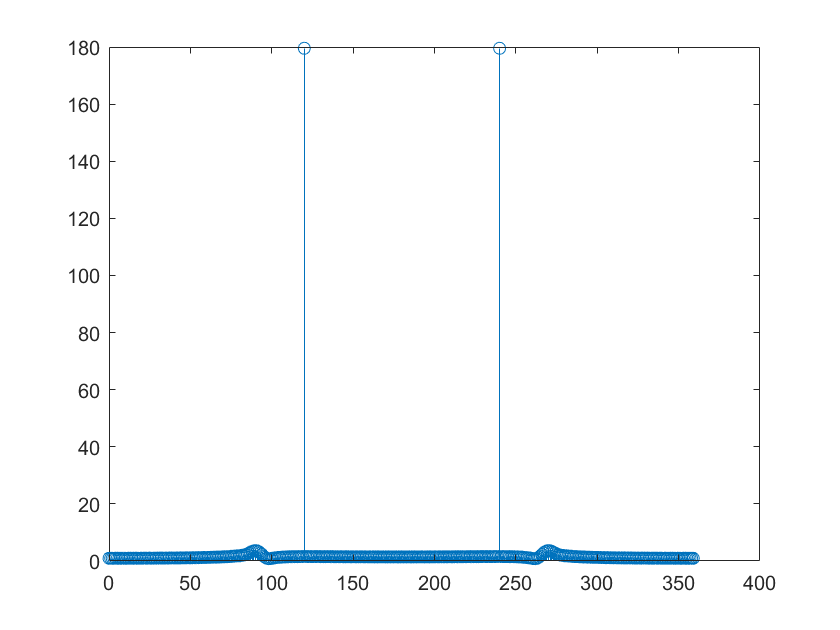

X=fft(x3);
mag=abs(X);
n=length(t);
df=fs/n;
f=df*(0:n-1);
figure
stem(f,mag)